%% Non-Convex Optimization using Particle Swarm Optimization (PSO)
%  Minimizes a non-convex function with multiple local minima.
%
%  Example objective (2D Ackley function – highly non-convex):
%    f(x) = -20*exp(-0.2*sqrt(0.5*(x1^2+x2^2)))
%           - exp(0.5*(cos(2*pi*x1)+cos(2*pi*x2))) + e + 20
%  Global minimum: f(0,0) = 0
%
%  PSO Update Equations:
%    v(t+1) = w*v(t) + c1*r1*(pbest - x) + c2*r2*(gbest - x)
%    x(t+1) = x(t) + v(t+1)
%
%  Author : Generated Example
%  Toolbox: None required – pure MATLAB implementation

clear; clc; close all;

%% ── 1. Objective Function ────────────────────────────────────────────────

% Ackley function (non-convex, deceptive landscape)
f = @(x) -20 * exp(-0.2 * sqrt(0.5*(x(1)^2 + x(2)^2))) ...
         - exp(0.5*(cos(2*pi*x(1)) + cos(2*pi*x(2)))) ...
         + exp(1) + 20;

n_vars = 2;
lb     = [-5, -5];
ub     = [ 5,  5];

%% ── 2. PSO Parameters ────────────────────────────────────────────────────

n_particles  = 50;       % Swarm size
max_iter     = 300;      % Maximum iterations

% Inertia weight (linearly decreasing: improves exploration → exploitation)
w_max        = 0.9;      % Initial inertia (exploration)
w_min        = 0.4;      % Final inertia   (exploitation)

c1           = 2.0;      % Cognitive coefficient (personal best attraction)
c2           = 2.0;      % Social coefficient    (global best attraction)

v_max        = 0.2 * (ub - lb);   % Max velocity per dimension
tol          = 1e-8;               % Convergence tolerance
stall_limit  = 60;                 % Stop if gbest unchanged for N iters

%% ── 3. Initialise Swarm ──────────────────────────────────────────────────

% Positions: uniform random within bounds
pos  = lb + rand(n_particles, n_vars) .* (ub - lb);

% Velocities: small random initialisation
vel  = -v_max + rand(n_particles, n_vars) .* (2 * v_max);

% Personal best
pbest     = pos;
pbest_fit = arrayfun(@(i) f(pos(i,:)), 1:n_particles)';

% Global best
[gbest_fit, gidx] = min(pbest_fit);
gbest             = pbest(gidx, :);

% History tracking
gbest_history     = zeros(max_iter, 1);
mean_fit_history  = zeros(max_iter, 1);
gbest_pos_history = zeros(max_iter, n_vars);
diversity_history = zeros(max_iter, 1);

stall_count = 0;
prev_gbest  = Inf;

fprintf('\n=================================================================\n');

fprintf('  Non-Convex Optimization  –  Particle Swarm Optimization (PSO)\n');

  Non-Convex Optimization  –  Particle Swarm Optimization (PSO)


fprintf('  Function : Ackley 2D   |   Global min f(0,0) = 0\n');

  Function : Ackley 2D   |   Global min f(0,0) = 0


fprintf('=================================================================\n');

fprintf('  Iter  |  gbest f(x)   |  Mean f(x)    |  gbest x1     |  gbest x2\n');

  Iter  |  gbest f(x)   |  Mean f(x)    |  gbest x1     |  gbest x2


fprintf('-----------------------------------------------------------------\n');

-----------------------------------------------------------------



%% ── 4. PSO Main Loop ─────────────────────────────────────────────────────

actual_iter = max_iter;

for t = 1:max_iter

    %% 4a. Linearly decreasing inertia weight
    w = w_max - (w_max - w_min) * (t / max_iter);

    %% 4b. Update velocity and position
    r1 = rand(n_particles, n_vars);   % Cognitive random factors
    r2 = rand(n_particles, n_vars);   % Social random factors

    % Velocity update
    vel = w * vel ...
        + c1 * r1 .* (pbest - pos) ...
        + c2 * r2 .* (gbest  - pos);

    % Clamp velocity
    vel = max(vel, -v_max);
    vel = min(vel,  v_max);

    % Position update
    pos = pos + vel;

    % Enforce bounds (reflect off walls)
    for d = 1:n_vars
        out_lo = pos(:,d) < lb(d);
        out_hi = pos(:,d) > ub(d);
        pos(out_lo, d) = lb(d);
        pos(out_hi, d) = ub(d);
        vel(out_lo, d) = -vel(out_lo, d);
        vel(out_hi, d) = -vel(out_hi, d);
    end

    %% 4c. Evaluate fitness
    fit = arrayfun(@(i) f(pos(i,:)), 1:n_particles)';

    %% 4d. Update personal bests
    improved = fit < pbest_fit;
    pbest(improved, :)  = pos(improved, :);
    pbest_fit(improved) = fit(improved);

    %% 4e. Update global best
    [iter_best_fit, iter_best_idx] = min(pbest_fit);
    if iter_best_fit < gbest_fit
        gbest_fit = iter_best_fit;
        gbest     = pbest(iter_best_idx, :);
    end

    %% 4f. Record history
    gbest_history(t)       = gbest_fit;
    mean_fit_history(t)    = mean(fit);
    gbest_pos_history(t,:) = gbest;
    diversity_history(t)   = mean(std(pos));   % Swarm diversity

    %% 4g. Stall detection
    if abs(gbest_fit - prev_gbest) < 1e-12
        stall_count = stall_count + 1;
    else
        stall_count = 0;
    end
    prev_gbest = gbest_fit;

    %% 4h. Print progress
    if t <= 5 || mod(t, 50) == 0
        fprintf('  %4d  | %13.6f | %13.6f | %13.6f | %13.6f\n', ...
            t, gbest_fit, mean(fit), gbest(1), gbest(2));
    end

    %% 4i. Convergence checks
    if gbest_fit < tol
        fprintf('\n  ✓ Global minimum found at iteration %d  (f* = %.2e)\n', t, gbest_fit);
        actual_iter = t;
        break
    end
    if stall_count >= stall_limit
        fprintf('\n  ✓ Stall limit reached at iteration %d  (no improvement for %d iters)\n', t, stall_limit);
        actual_iter = t;
        break
    end
end

     1  |      0.867090 |      7.642146 |     -0.139249 |     -0.030834
     2  |      0.867090 |      5.358152 |     -0.139249 |     -0.030834
     3  |      0.867090 |      6.019614 |     -0.139249 |     -0.030834
     4  |      0.867090 |      4.684685 |     -0.139249 |     -0.030834
     5  |      0.867090 |      5.629413 |     -0.139249 |     -0.030834
    50  |      0.007293 |      3.085877 |     -0.001031 |      0.002298
   100  |      0.000330 |      1.315373 |     -0.000065 |      0.000097
   150  |      0.000053 |      0.245356 |     -0.000019 |      0.000001
   200  |      0.000000 |      0.004970 |      0.000000 |     -0.000000



  ✓ Global minimum found at iteration 201  (f* = 3.14e-09)



% Trim history arrays
gbest_history     = gbest_history(1:actual_iter);
mean_fit_history  = mean_fit_history(1:actual_iter);
gbest_pos_history = gbest_pos_history(1:actual_iter, :);
diversity_history = diversity_history(1:actual_iter);

%% ── 5. Final Results ─────────────────────────────────────────────────────

fprintf('\n=================================================================\n');

fprintf('  Final Results\n');

  Final Results


fprintf('=================================================================\n');

fprintf('  Optimal x1     = %14.10f\n', gbest(1));

  Optimal x1     =   0.0000000011


fprintf('  Optimal x2     = %14.10f\n', gbest(2));

  Optimal x2     =  -0.0000000003


fprintf('  Optimal f(x*)  = %14.10f\n', gbest_fit);

  Optimal f(x*)  =   0.0000000031


fprintf('  Known global   =   0.0000000000  at (0, 0)\n');

  Known global   =   0.0000000000  at (0, 0)


fprintf('  Position error = %14.2e\n',  norm(gbest));

  Position error =       1.11e-09


fprintf('  Iterations     = %d\n',       actual_iter);

  Iterations     = 201


fprintf('=================================================================\n\n');

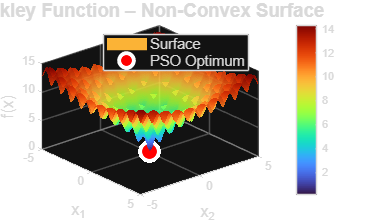


%% ── 6. Visualisation ─────────────────────────────────────────────────────

% ── 6a. 3D Surface of the Ackley function ────────────────────────────────
figure('Name','Ackley Surface','NumberTitle','off','Color','w');
[X1, X2] = meshgrid(linspace(-5, 5, 300));
F_surf = -20*exp(-0.2*sqrt(0.5*(X1.^2+X2.^2))) ...
         - exp(0.5*(cos(2*pi*X1)+cos(2*pi*X2))) + exp(1) + 20;

surf(X1, X2, F_surf, 'EdgeColor','none','FaceAlpha',0.88);
colormap(turbo); colorbar;
hold on;
plot3(gbest(1), gbest(2), gbest_fit+0.3, ...
      'wo','MarkerSize',14,'LineWidth',3,'MarkerFaceColor','r');
xlabel('x_1','FontSize',12); ylabel('x_2','FontSize',12);
zlabel('f(x)','FontSize',12);
title('Ackley Function – Non-Convex Surface','FontSize',14,'FontWeight','bold');
legend({'Surface','PSO Optimum'},'FontSize',11,'Location','northeast');
view(50, 35); hold off;

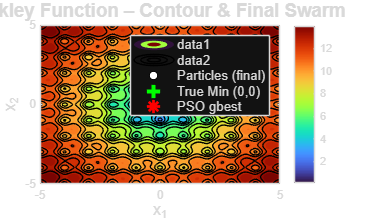


% ── 6b. Contour with swarm positions at final iteration ──────────────────
figure('Name','Contour + Swarm','NumberTitle','off','Color','w');
contourf(X1, X2, F_surf, 40,'LineColor','none'); colormap(turbo); colorbar;
hold on;
contour(X1, X2, F_surf, 20,'k','LineWidth',0.4);
scatter(pos(:,1), pos(:,2), 40, 'w', 'filled', 'MarkerEdgeColor','k', ...
        'LineWidth',0.5, 'DisplayName','Particles (final)');
plot(0, 0, 'g+','MarkerSize',18,'LineWidth',3,'DisplayName','True Min (0,0)');
plot(gbest(1), gbest(2), 'r*','MarkerSize',14,'LineWidth',2,'DisplayName','PSO gbest');
xlabel('x_1','FontSize',12); ylabel('x_2','FontSize',12);
title('Ackley Function – Contour & Final Swarm','FontSize',14,'FontWeight','bold');
legend('FontSize',10,'Location','northeast'); hold off;

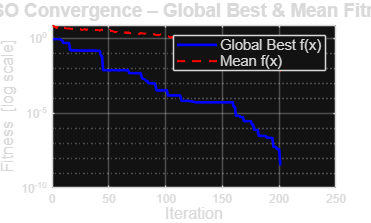


% ── 6c. Convergence: gbest and mean fitness ───────────────────────────────
figure('Name','PSO Convergence','NumberTitle','off','Color','w');
iters = 1:actual_iter;
semilogy(iters, gbest_history,    'b-',  'LineWidth',2,'DisplayName','Global Best f(x)');
hold on;
semilogy(iters, mean_fit_history, 'r--', 'LineWidth',1.5,'DisplayName','Mean f(x)');
xlabel('Iteration','FontSize',12);
ylabel('Fitness  [log scale]','FontSize',12);
title('PSO Convergence – Global Best & Mean Fitness','FontSize',14,'FontWeight','bold');
legend('FontSize',11); grid on; box on; hold off;

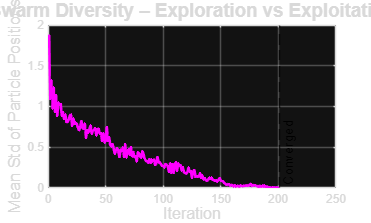


% ── 6d. Swarm diversity over iterations ──────────────────────────────────
figure('Name','Swarm Diversity','NumberTitle','off','Color','w');
plot(iters, diversity_history, 'm-', 'LineWidth',2);
xlabel('Iteration','FontSize',12);
ylabel('Mean Std of Particle Positions','FontSize',12);
title('Swarm Diversity – Exploration vs Exploitation','FontSize',14,'FontWeight','bold');
grid on; box on;
xline(actual_iter, 'k--', 'Converged','FontSize',10,'LabelVerticalAlignment','bottom');

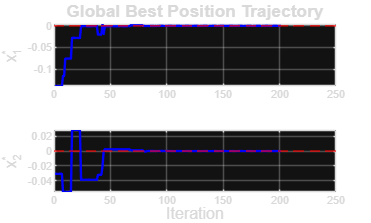


% ── 6e. gbest trajectory (x1 and x2 vs iteration) ────────────────────────
figure('Name','gbest Trajectory','NumberTitle','off','Color','w');
subplot(2,1,1);
plot(iters, gbest_pos_history(:,1), 'b-', 'LineWidth',1.8);
yline(0,'r--','LineWidth',1.2); ylabel('x_1^*','FontSize',12);
title('Global Best Position Trajectory','FontSize',13,'FontWeight','bold');
grid on;
subplot(2,1,2);
plot(iters, gbest_pos_history(:,2), 'b-', 'LineWidth',1.8);
yline(0,'r--','LineWidth',1.2);
xlabel('Iteration','FontSize',12); ylabel('x_2^*','FontSize',12);
grid on;


%% ── 7. Multi-Run Study (10 runs) ─────────────────────────────────────────

n_runs   = 10;
run_best = zeros(n_runs,1);
run_soln = zeros(n_runs, n_vars);
run_iter = zeros(n_runs,1);

fprintf('  Running PSO %d independent times...\n\n', n_runs);

  Running PSO 10 independent times...



fprintf('  Run |  f(x*)        |  x1*          |  x2*          |  Iters\n');

  Run |  f(x*)        |  x1*          |  x2*          |  Iters


fprintf('  ----------------------------------------------------------------\n');

  ----------------------------------------------------------------



for r = 1:n_runs
    p_r   = lb + rand(n_particles,n_vars).*(ub-lb);
    v_r   = -v_max + rand(n_particles,n_vars).*(2*v_max);
    pb_r  = p_r;
    pbf_r = arrayfun(@(i) f(p_r(i,:)), 1:n_particles)';
    [gbf_r, gi] = min(pbf_r);
    gb_r  = pb_r(gi,:);
    sc_r  = 0;  pg_r = Inf;

    for t = 1:max_iter
        w_r = w_max - (w_max-w_min)*(t/max_iter);
        r1_r = rand(n_particles,n_vars);
        r2_r = rand(n_particles,n_vars);
        v_r  = w_r*v_r + c1*r1_r.*(pb_r-p_r) + c2*r2_r.*(gb_r-p_r);
        v_r  = max(min(v_r,v_max),-v_max);
        p_r  = p_r + v_r;
        p_r  = max(min(p_r,ub),lb);
        ft_r = arrayfun(@(i) f(p_r(i,:)), 1:n_particles)';
        imp  = ft_r < pbf_r;
        pb_r(imp,:) = p_r(imp,:);
        pbf_r(imp)  = ft_r(imp);
        [ibf,ii] = min(pbf_r);
        if ibf < gbf_r; gbf_r = ibf; gb_r = pb_r(ii,:); end
        if abs(gbf_r-pg_r)<1e-12; sc_r=sc_r+1; else; sc_r=0; end
        pg_r = gbf_r;
        if gbf_r<tol || sc_r>=stall_limit
            run_iter(r)=t; break;
        end
        if t==max_iter; run_iter(r)=max_iter; end
    end

    run_best(r)   = gbf_r;
    run_soln(r,:) = gb_r;
    fprintf('  %3d | %13.6f | %13.6f | %13.6f | %6d\n', ...
            r, gbf_r, gb_r(1), gb_r(2), run_iter(r));
end

    1 |      0.000000 |     -0.000000 |      0.000000 |    217
    2 |      0.000000 |     -0.000000 |      0.000000 |    230
    3 |      0.000000 |      0.000000 |      0.000000 |    212
    4 |      0.000000 |     -0.000000 |     -0.000000 |    227
    5 |      0.000000 |     -0.000000 |     -0.000000 |    226
    6 |      0.000000 |     -0.000000 |     -0.000000 |    236
    7 |      0.000000 |      0.000000 |      0.000000 |    224
    8 |      0.000000 |     -0.000000 |      0.000000 |    236
    9 |      0.000000 |     -0.000000 |      0.000000 |    215
   10 |      0.000000 |      0.000000 |      0.000000 |    219



fprintf('\n  Multi-run Summary (%d runs):\n', n_runs);


  Multi-run Summary (10 runs):


fprintf('  Mean f*   = %.8f\n',  mean(run_best));

  Mean f*   = 0.00000001


fprintf('  Std  f*   = %.8f\n',  std(run_best));

  Std  f*   = 0.00000000


fprintf('  Best f*   = %.8f\n',  min(run_best));

  Best f*   = 0.00000000


fprintf('  Worst f*  = %.8f\n',  max(run_best));

  Worst f*  = 0.00000001


fprintf('  Mean iters= %.1f\n\n', mean(run_iter));

  Mean iters= 224.2

